clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");
d6=load("VODCA VOD\VOD_X_zscore.mat");
d7=load("VODCA VOD\VOD_C_zscore.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);
vod_x=d6.Z(:,:,1:132);
vod_c=d7.Z(:,:,1:132);

clear f1;
clear f2;
clear f3;
clear f4;
clear f5;
clear f6;
clear f7;
clear f8;
clear f10;
clear f12;

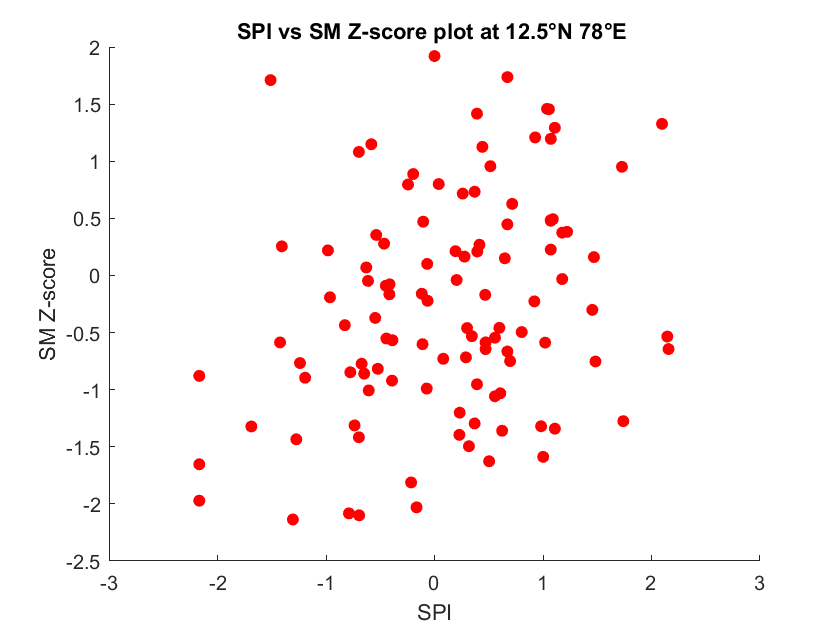

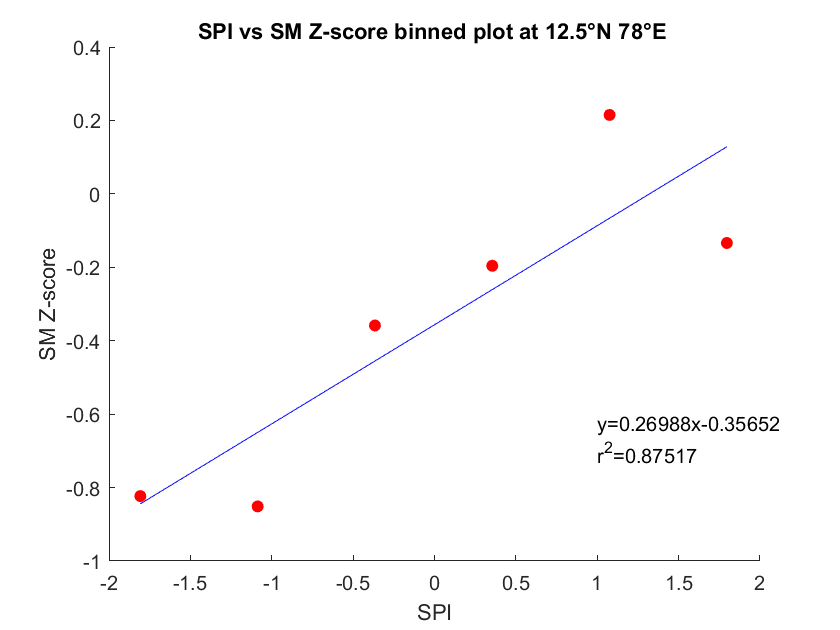

xx="SPI";
yy="SM Z-score";
xp=26;
yp=48;
lat=spi(xp,1,1);
long=spi(1,yp,1);

for x = xp              %setting lat values
    for y = yp          %setting long values
        
        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)= sm(x,y,:);
        
        f1=figure(1);
        scatter(squeeze(X),squeeze(Y),'red',"filled")
        hold on
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        %             clear X1;clear Y1;
        hold off
        saveas(f1,"E:\MTP2\MTP2 final results\TN\1 SM scatter\1.png");
        
        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);
        
        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end
        
        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];
        
        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end
        
        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];
        
        mdl=fitlm(X1,Y1);
        
        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);
        
        D=slope*X1+intercept;
        
       
        f2=figure(2);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" binned plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r^2="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.5,yt)
        %             clear X1;clear Y1;
        hold off
        saveas(f2,"E:\MTP2\MTP2 final results\TN\1 SM scatter\2.png");
        
    end
end

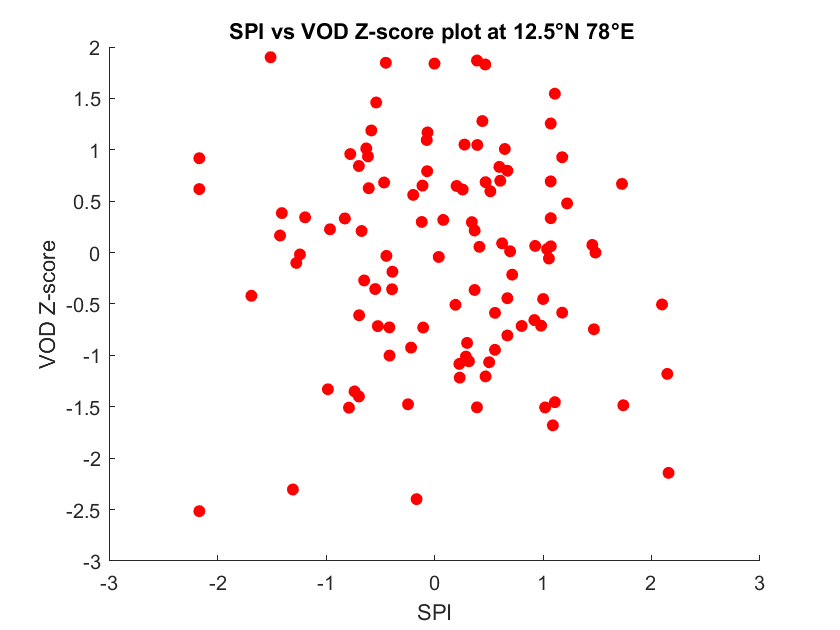

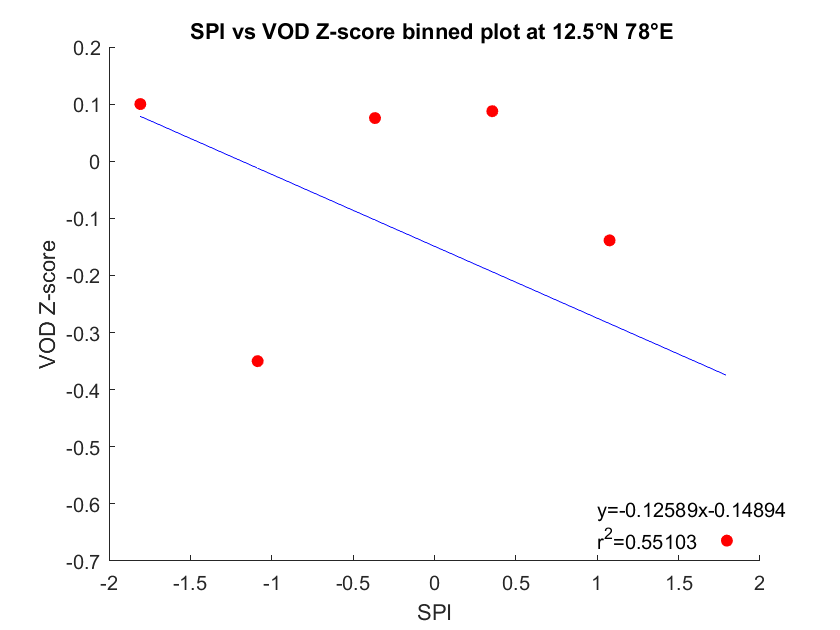

xx="SPI";
yy="VOD Z-score";


for x = xp              %setting lat values
    for y = yp         %setting long values

        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)= vod(x,y,:);

        f3=figure(3);
        scatter(squeeze(X),squeeze(Y),'red',"filled")
        hold on
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        %             clear X1;clear Y1;
        hold off
        saveas(f3,"E:\MTP2\MTP2 final results\TN\2 VOD scatter\1.png");

        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);

        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end

        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];

        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end

        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];

        mdl=fitlm(X1,Y1);

        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);

        D=slope*X1+intercept;

       
        f4=figure(4);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" binned plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r^2="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.1,yt)
        %             clear X1;clear Y1;
        hold off
        saveas(f4,"E:\MTP2\MTP2 final results\TN\2 VOD scatter\2.png");
    end
end

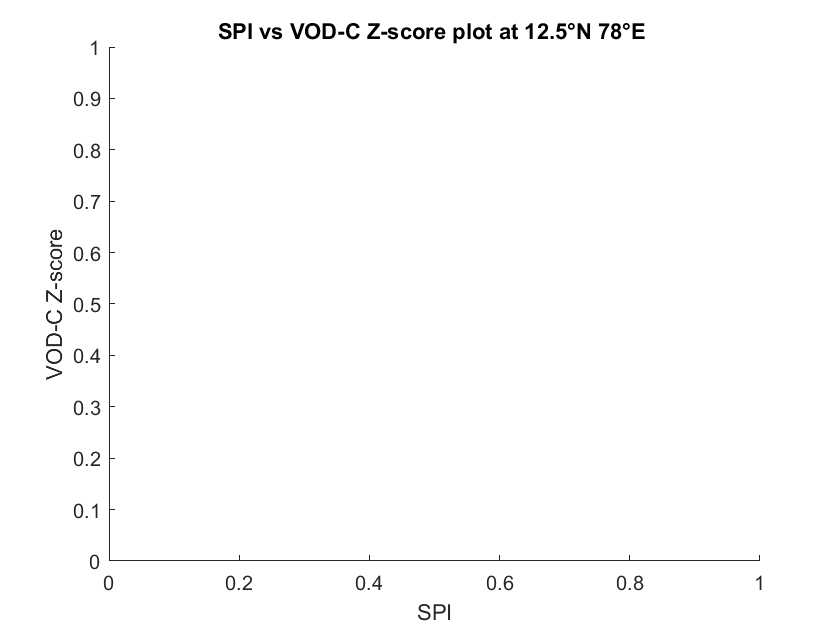

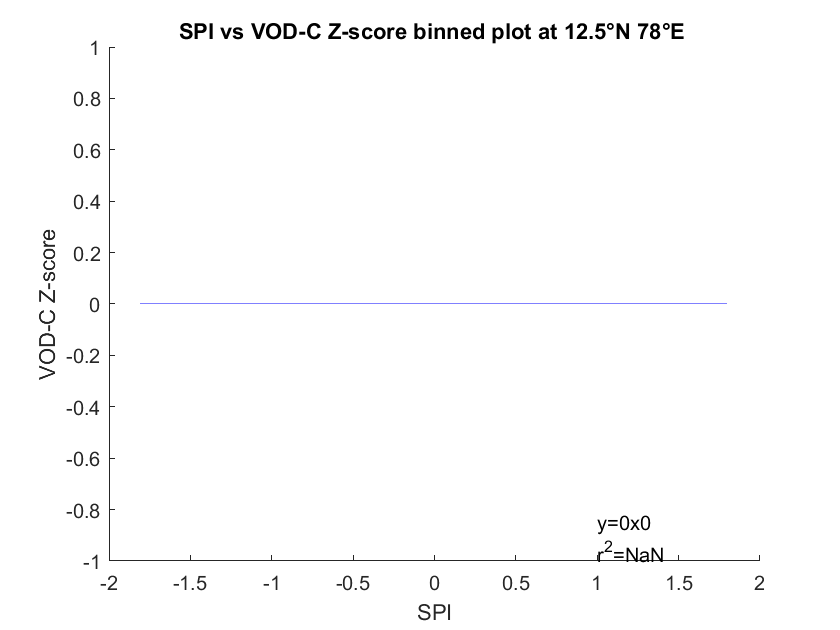

xx="SPI";
yy="VOD-C Z-score";


for x = xp              %setting lat values
    for y = yp          %setting long values

        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)=vod_c(x,y,:);

        f10=figure(10);
        scatter(squeeze(X),squeeze(Y),'red',"filled")
        hold on
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        %             clear X1;clear Y1;
        hold off
        saveas(f10,"E:\MTP2\MTP2 final results\TN\3 VOD-C scatter\1.png");
        
        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);

        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end

        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];

        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end

        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];

        mdl=fitlm(X1,Y1);

        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);

        D=slope*X1+intercept;

        
        f12=figure(12);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" binned plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r^2="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.1,yt)
        %             clear X1;clear Y1;
        hold off
        saveas(f12,"E:\MTP2\MTP2 final results\TN\3 VOD-C scatter\2.png");

    end
end

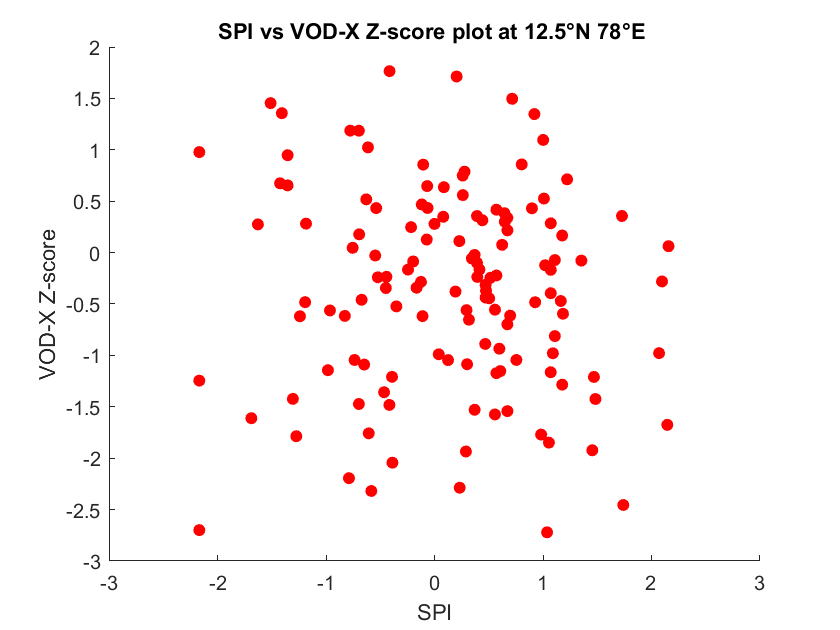

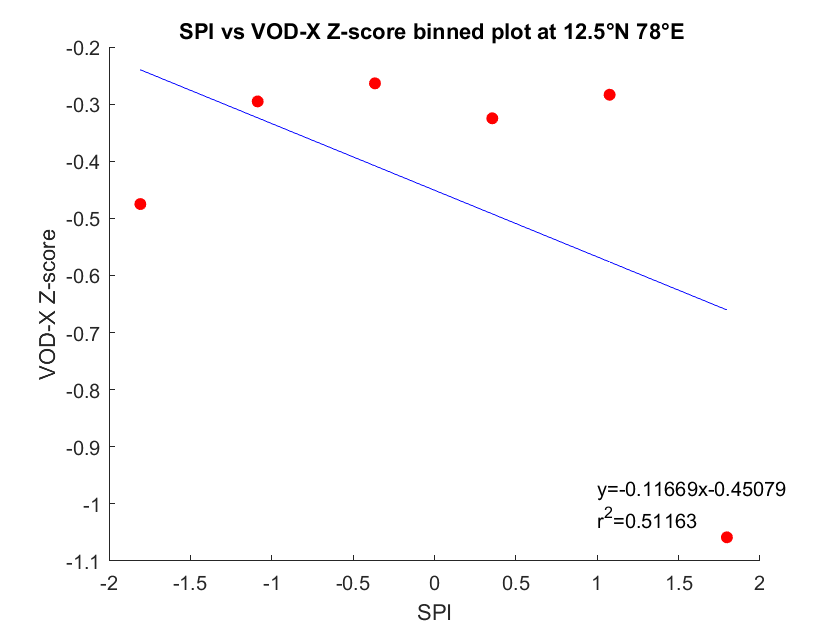

xx="SPI";
yy="VOD-X Z-score";


for x = xp              %setting lat values
    for y = yp          %setting long values
        
        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)=vod_x(x,y,:);
        
        f5=figure(5);
        scatter(squeeze(X),squeeze(Y),'red',"filled")
        hold on
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        %             clear X1;clear Y1;
        hold off
        saveas(f5,"E:\MTP2\MTP2 final results\TN\4 VOD-X scatter\1.png");
        
        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);
        
        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end
        
        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];
        
        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end
        
        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];
        
        mdl=fitlm(X1,Y1);
        
        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);
        
        D=slope*X1+intercept;
        
        
        f6=figure(6);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" binned plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r^2="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.1,yt)
        %             clear X1;clear Y1;
        hold off
        saveas(f6,"E:\MTP2\MTP2 final results\TN\4 VOD-X scatter\2.png");
    end
end

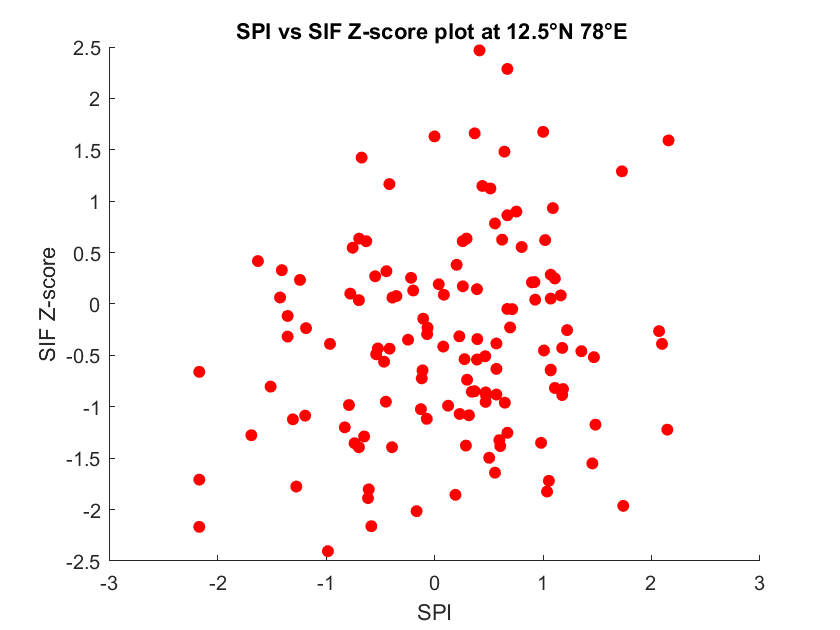

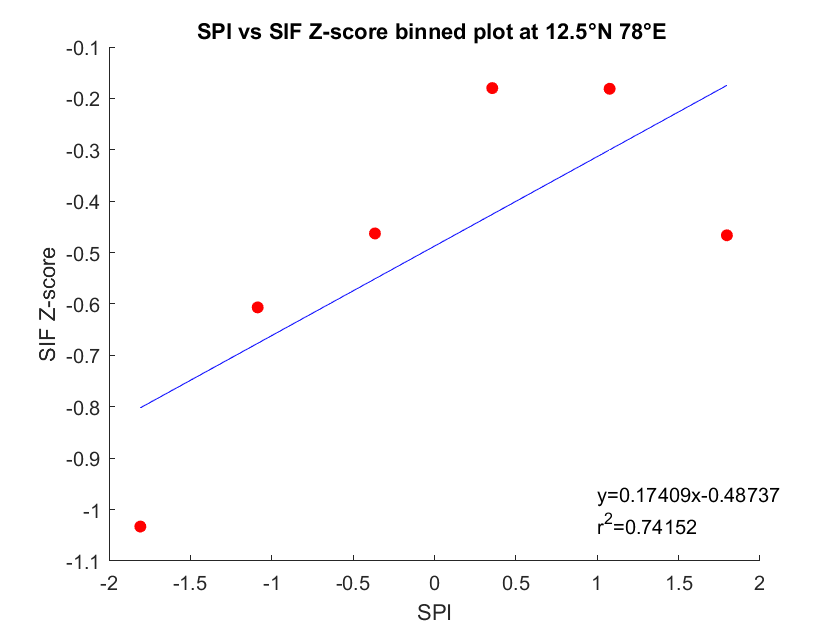

xx="SPI";
yy="SIF Z-score";


for x = xp              %setting lat values
    for y = yp          %setting long values
        
        X=zeros(132,1);
        Y=zeros(132,1);
        X(:,1)=spi(x,y,:);
        Y(:,1)=sif(x,y,:);
        
        f7=figure(7);
        scatter(squeeze(X),squeeze(Y),'red',"filled")
        hold on
        title(xx+" vs "+yy+" plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        %             clear X1;clear Y1;
        hold off
        saveas(f7,"E:\MTP2\MTP2 final results\TN\5 SIF scatter\1.png");
        
        xmax=max(X);
        xmin=min(X);
        step_x=(xmax-xmin)/6;
        rangex=[xmin:step_x:xmax]';
        lenr_x=length(rangex);
        
        for i = 2:lenr_x
            X1(i-1,1)=(rangex(i)+rangex(i-1))/2;
        end
        
        %ymax=max(Y);
        %ymin=min(Y);
        %step=(ymax-ymin)/6;
        %range_y=[ymin:step:ymax]';
        %lenr_y=length(range_y);
        y1=[];y2=[];y3=[];y4=[];y5=[];y6=[];
        
        for i=1:132
            if isnan(Y(i)) || isnan(X(i))
                continue;
            elseif X(i)>=rangex(1) & X(i)<rangex(2)
                y1=[y1;Y(i)];
            elseif X(i)>=rangex(2) & X(i)<rangex(3)
                y2=[y2;Y(i)];
            elseif X(i)>=rangex(3) & X(i)<rangex(4)
                y3=[y3;Y(i)];
            elseif X(i)>=rangex(4) & X(i)<rangex(5)
                y4=[y4;Y(i)];
            elseif X(i)>=rangex(5) & X(i)<rangex(6)
                y5=[y5;Y(i)];
            elseif X(i)>=rangex(6) & X(i)<=rangex(7)
                y6=[y6;Y(i)];
            end
        end
        
        Y1=[mean(y1);mean(y2);mean(y3);mean(y4);mean(y5);mean(y6)];
        
        mdl=fitlm(X1,Y1);
        
        intercept=mdl.Coefficients.Estimate(1,1);
        slope=mdl.Coefficients.Estimate(2,1);
        r=sqrt(mdl.Rsquared.Ordinary);
        
        D=slope*X1+intercept;
        
       
        f8=figure(8);
        scatter(X1,Y1,'red',"filled")
        hold on
        plot(X1,D,"b")
        title(xx+" vs "+yy+" binned plot"+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
        xlabel(xx);
        ylabel(yy);
        yt="y="+num2str(slope)+"x"+num2str(intercept)+newline+"r^2="+num2str(r);
        ylim=get(gca,'ylim');
        xlim=get(gca,'xlim');
        text(xlim(2)/2,ylim(1)/1.1,yt)
        %             clear X1;clear Y1;
        hold off
        saveas(f8,"E:\MTP2\MTP2 final results\TN\5 SIF scatter\2.png");
    end
end

% xx="SPI";
% X=zeros(132,1);
% Y=zeros(132,1);
% X(:,1)=spi(x,y,:);
% Y(:,1)=sif(x,y,:);
% date=squeeze(spi(1,1,:));
% %dt=datetime(num2str(date(:)), 'yyyy-MM');
% dt =  datetime(fix(date/100),rem(date,100), ones(size(date)), 'Format','MM/dd/yyyy');
% %dt = datetime(num2str(date), 'ConvertFrom','yyyy-MM');
% 
% f9=figure(9);
% plot(dt(25:132),X(25:132),'r');
% %ylim([-3 3])
% ylabel("SPI")
% hold on
% legend(xx);
% legend boxoff;
% j=yline(0);
% j.Annotation.LegendInformation.IconDisplayStyle = 'off';
% title("Time series of "+xx+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
% hold off

% xx="VOD";
% X=zeros(132,1);
% Y=zeros(132,1);
% X(:,1)=spi(x,y,:);
% Y(:,1)=vod(x,y,:);
% date=squeeze(vod(1,1,:));
% %dt=datetime(num2str(date(:)), 'yyyy-MM');
% dt =  datetime(fix(date/100),rem(date,100), ones(size(date)), 'Format','MM/dd/yyyy');
% %dt = datetime(num2str(date), 'ConvertFrom','yyyy-MM');
% 
% f9=figure(9);
% plot(dt(25:132),Y(25:132),'r');
% %ylim([-3 3])
% ylabel("VOD")
% hold on
% legend(xx);
% legend boxoff;
% j=yline(0);
% j.Annotation.LegendInformation.IconDisplayStyle = 'off';
% title("Time series of "+xx+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
% hold off

% xx="VOD-C";
% X=zeros(132,1);
% Y=zeros(132,1);
% X(:,1)=spi(x,y,:);
% Y(:,1)=vod_c(x,y,:);
% date=squeeze(vod(1,1,:));
% %dt=datetime(num2str(date(:)), 'yyyy-MM');
% dt =  datetime(fix(date/100),rem(date,100), ones(size(date)), 'Format','MM/dd/yyyy');
% %dt = datetime(num2str(date), 'ConvertFrom','yyyy-MM');
% 
% f9=figure(9);
% plot(dt(25:132),Y(25:132),'r');
% %ylim([-3 3])
% ylabel("VOD-C")
% hold on
% legend(xx);
% legend boxoff;
% j=yline(0);
% j.Annotation.LegendInformation.IconDisplayStyle = 'off';
% title("Time series of "+xx+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
% hold off

% xx="VOD-X";
% X=zeros(132,1);
% Y=zeros(132,1);
% X(:,1)=spi(x,y,:);
% Y(:,1)=vod_x(x,y,:);
% date=squeeze(vod(1,1,:));
% %dt=datetime(num2str(date(:)), 'yyyy-MM');
% dt =  datetime(fix(date/100),rem(date,100), ones(size(date)), 'Format','MM/dd/yyyy');
% %dt = datetime(num2str(date), 'ConvertFrom','yyyy-MM');
% 
% f9=figure(9);
% plot(dt(25:132),Y(25:132),'r');
% %ylim([-3 3])
% ylabel("VOD-X")
% hold on
% legend(xx);
% legend boxoff;
% j=yline(0);
% j.Annotation.LegendInformation.IconDisplayStyle = 'off';
% title("Time series of "+xx+" at "+num2str(lat)+"°N "+num2str(long)+"°E ");
% hold off